To determine the inertia for each axis the following equations is used.


$$I = \frac{T^2\cdot m\cdot g \cdot b^2 }{16\cdot \pi^2\cdot L}$$


T: osccilation period

m: mass of object

g: acceleration of earths grvity

b:distance between robes 

L: length from ankers to center of gravity 

### Parameters   

m = 1.513 %kh

m = 1.5130

g = 9.82  %kg/s^2

g = 9.8200

b = 0.128 % m

b = 0.1280

### L

The parameter L is  the same for roll and yaw and different for pitch

L = 0.28m for (roll and yaw) 

L = 0.20m for pitch 

A swing test was executed for each axis, and is now used to determine the oscilation period

#### Inertia for roll

data = readmatrix("Data/Swing_Roll3.txt")

data =    -0.5763   -0.0388    2.3481
   -0.6052   -0.0988    1.9353
   -0.5965   -0.0625    1.5803
   -0.6424   -0.0893    1.1726
   -0.6283   -0.0688    0.7969
   -0.6365   -0.0896    0.3914
   -0.6504   -0.1370   -0.0050
   -0.6565   -0.0919   -0.3240
   -0.6770   -0.0835   -0.6374
   -0.6717   -0.1250   -0.9510



t = (0:length(data)-1)/30

t =          0    0.0333    0.0667    0.1000    0.1333    0.1667    0.2000    0.2333    0.2667    0.3000    0.3333    0.3667    0.4000    0.4333    0.4667    0.5000    0.5333    0.5667    0.6000    0.6333    0.6667    0.7000    0.7333    0.7667    0.8000    0.8333    0.8667    0.9000    0.9333    0.9667    1.0000    1.0333    1.0667    1.1000    1.1333    1.1667    1.2000    1.2333    1.2667    1.3000    1.3333    1.3667    1.4000    1.4333    1.4667    1.5000    1.5333    1.5667    1.6000    1.6333


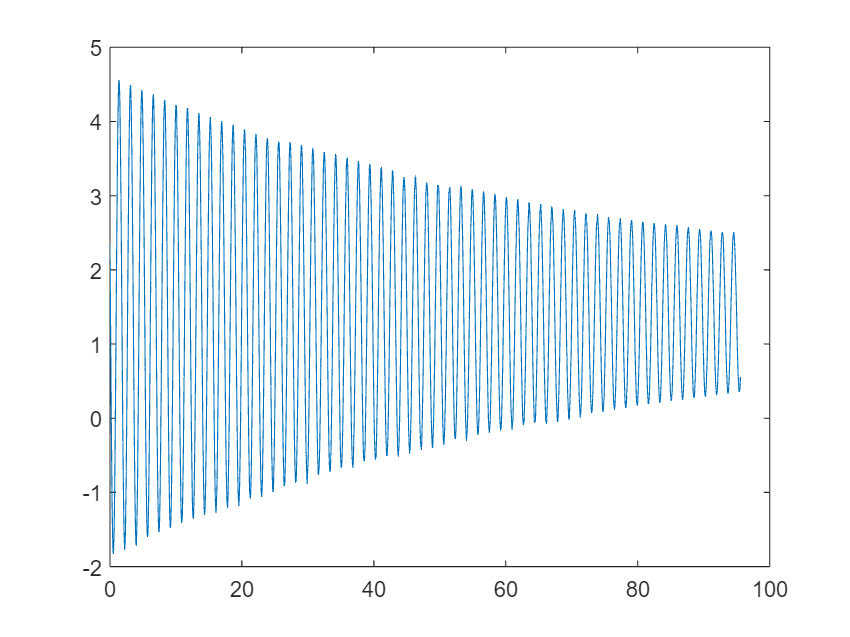

plot(t, data(:,3))



[pcs,lcks] = findpeaks(data(:,3),t,MinPeakWidth=0.5)

'findpeaks' requires Signal Processing Toolbox.

period = mean(diff(lcks))

I_roll=(period^2*m*g*b^2)/(16*pi^2*0.25) 


#### Inertia for pitch 

data = readmatrix("Data/Swing_Pitch3.txt")
data = data(6060:end,:) % remove the first 2070 samples since the swing hasent begun oscilation yet.
t = (0:length(data)-1)/30
plot(t, data(:,3))


[pcs,lcks] = findpeaks(data(:,3),t,MinPeakWidth=0.5)
period = mean(diff(lcks))

I_Pitch=(period^2*m*g*b^2)/(16*pi^2*0.28) 

### Inertia for yaw

data = readmatrix("Data/Swing_Yaw.txt")
data = data(1560:end,:) %remove the first 2070 samples since the swing hasent begun oscilation yet.
t = (0:length(data)-1)/30
plot(t, data(:,3))


[pcs,lcks] = findpeaks(data(:,3),t,MinPeakWidth=0.6)
period = mean(diff(lcks))

I_Yaw=(period^2*m*g*b^2)/(16*pi^2*0.28) 

### Inetias

I_roll
I_Pitch
I_Yaw